**Solve Differential Equation**

Specify a differential equation by using `==` and represent differentiation by using the [`diff`](https://www.mathworks.com/help/symbolic/diff.html) function. Then, solve the equation by using `dsolve`.

Solve the equation *d**y**d**t*=*a**y*.

`syms a y(t)`

`eqn = diff(y,t) == a*y;`

`dsolve(eqn)`

`ans =`

`C2*exp(a*t)`

`C2` is a constant. To eliminate constants, see [Solve Differential Equation with Condition](https://www.mathworks.com/help/symbolic/dsolve.html#bve5nw0-1). For a full workflow, see [Solving Partial Differential Equations](https://www.mathworks.com/help/symbolic/examples/solve-a-partial-differential-equation-tsunami-simulation.html). For more examples, see [Solve Differential Equation](https://www.mathworks.com/help/symbolic/dsolve.html#bve5ngf-2).

**Solve Higher-Order Differential Equation**

Specify the second-order derivative of a function `y` by using `diff(y,t,2)` or `diff(y,t,t)`. Similarly, specify the n-th order derivative by using `diff(y,t,n)`.

Solve the equation *d*2*y**d**t*2=*a**y*.

`syms y(t) a`

`eqn = diff(y,t,2) == a*y;`

`ySol(t) = dsolve(eqn)`

`ySol(t) =`

`C2*exp(-a^(1/2)*t) + C3*exp(a^(1/2)*t)`

**Solve Differential Equation with Condition**

Specify conditions as the second input to `dsolve` by using the `==` operator. Specifying conditions eliminates arbitrary constants, such as `C1`, `C2`,`...` from the solution.

Solve the equation *d**y**d**t*=*a**y* with the condition *y*(0)=5.

`syms y(t) a`

`eqn = diff(y,t) == a*y;`

`cond = y(0) == 5;`

`ySol(t) = dsolve(eqn,cond)`

`ySol(t) =`

`5*exp(a*t)`

Solve the second-order differential equation *d*2*y**d**t*2=*a*2*y* with two conditions, *y*(0)=*b* and *y*′(0)=1. Create the second condition by assigning `diff(y,t)` to `Dy` and then using `Dy(0) == 1`.

`syms y(t) a b`

`eqn = diff(y,t,2) == a^2*y;`

`Dy = diff(y,t);`

`cond = [y(0)==b, Dy(0)==1];`

`ySol(t) = dsolve(eqn,cond)`

`ySol(t) =`

`(exp(a*t)*(a*b + 1))/(2*a) + (exp(-a*t)*(a*b - 1))/(2*a)`

Since two conditions are specified here, constants are eliminated from the solution of the second-order equation. In general, to eliminate constants from the solution, the number of conditions must equal the order of the equation.

**Solve System of Differential Equations**

Solve a system of differential equations by specifying the equations as a vector. `dsolve` returns a structure containing the solutions.

Solve the system of equations

*d**y**d**t*=*z**d**z**d**t*=−*y*.

`syms y(t) z(t)`

`eqns = [diff(y,t) == z, diff(z,t) == -y];`

`sol = dsolve(eqns)`

`sol = `

`  struct with fields:`

`    z: [1×1 sym]`

`    y: [1×1 sym]`

Access the solutions by addressing the elements of the structure.

`soly(t) = sol.y`

`soly(t) =`

`C2*cos(t) + C1*sin(t)`

`solz(t) = sol.z`

`solz(t) =`

`C1*cos(t) - C2*sin(t)`

**Assign Outputs to Functions or Variables**

When solving for multiple functions, `dsolve` returns a structure by default. Alternatively, you can directly assign solutions to functions or variables by specifying the outputs explicitly as a vector. `dsolve` sorts outputs in alphabetical order using [`symvar`](https://www.mathworks.com/help/symbolic/symvar.html).

Solve a system of differential equations and assign the outputs to functions.

`syms y(t) z(t)`

`eqns = [diff(y,t)==z, diff(z,t)==-y];`

`[ySol(t) zSol(t)] = dsolve(eqns)`

`ySol(t) =`

`C2*cos(t) + C1*sin(t)`

`zSol(t) =`

`C1*cos(t) - C2*sin(t)`

**When No Solutions Are Found**

If `dsolve` cannot solve your equation, then try solving the equation numerically. See [Solve a Second-Order Differential Equation Numerically](https://www.mathworks.com/help/symbolic/solve-differential-equation-numerically-1.html).

`syms y(x)`

`eqn = diff(y, 2) == (1 - y^2)*diff(y) - y;`

`dsolve(eqn)`

` Warning: Unable to find explicit solution. `

`> In dsolve (line 201) `

`ans =`

`[ empty sym ]`

**Include Special Cases by Turning Off Internal Simplifications**

By default, `dsolve` applies simplifications that are not generally correct, but produce simpler solutions. For details, see [Algorithms](https://www.mathworks.com/help/symbolic/dsolve.html#bve8y14-5). Instead, include these special cases by turning off these simplifications.

Solve *d**y**d**t*=*a*G*y*+*y* where *y*(*a*)=1 with and without simplifications. Turn off simplifications by setting ‘`IgnoreAnalyticConstraints`’ to `false`.

`syms a y(t)`

`eqn = diff(y) == a/sqrt(y) + y;`

`cond = y(a) == 1;`

`withSimplifications = dsolve(eqn, cond)`

`withSimplifications =`

`(exp((3*t)/2 - (3*a)/2 + log(a + 1)) - a)^(2/3)`

`withoutSimplifications = dsolve(eqn, cond, 'IgnoreAnalyticConstraints', false)`

`withoutSimplifications =`

`piecewise(pi/2 < angle(-a), {piecewise(in(C11, 'integer'),...`

` (- a + exp((3*t)/2 - (3*a)/2 + log(a + 1) + pi*C11*2i))^(2/3))},...`

` angle(-a) <= -pi/2, {piecewise(in(C12, 'integer'),...`

` (- a + exp((3*t)/2 - (3*a)/2 + log(a + 1) + pi*C12*2i))^(2/3))},...`

` angle(-a) in Dom::Interval(-pi/2, [pi/2]), {piecewise(in(C13, 'integer'),...`

` (- a + exp((3*t)/2 - (3*a)/2 + log(a + 1) + pi*C13*2i))^(2/3))})`

`withSimplifications` is easy to use but incomplete, while `withoutSimplifications` includes special cases but is not easy to use.

Further, for certain equations, `dsolve` cannot find an explicit solution if you set ‘`IgnoreAnalyticConstraints`’ to `false`.

syms f(t)

ode = diff(f,t) == -0.9 * f(t) + 25 * exp(-0.8 * t); 
ySol(t) = dsolve(ode)

$$ySol(t) = 250\,{\mathrm{e}}^{t/10}\,{\mathrm{e}}^{-\frac{9\,t}{10}}+C_{1}\,{\mathrm{e}}^{-\frac{9\,t}{10}}$$

cond = f(0) == 4;
ySol(t) = dsolve(ode,cond)

$$ySol(t) = 250\,{\mathrm{e}}^{t/10}\,{\mathrm{e}}^{-\frac{9\,t}{10}}-246\,{\mathrm{e}}^{-\frac{9\,t}{10}}$$

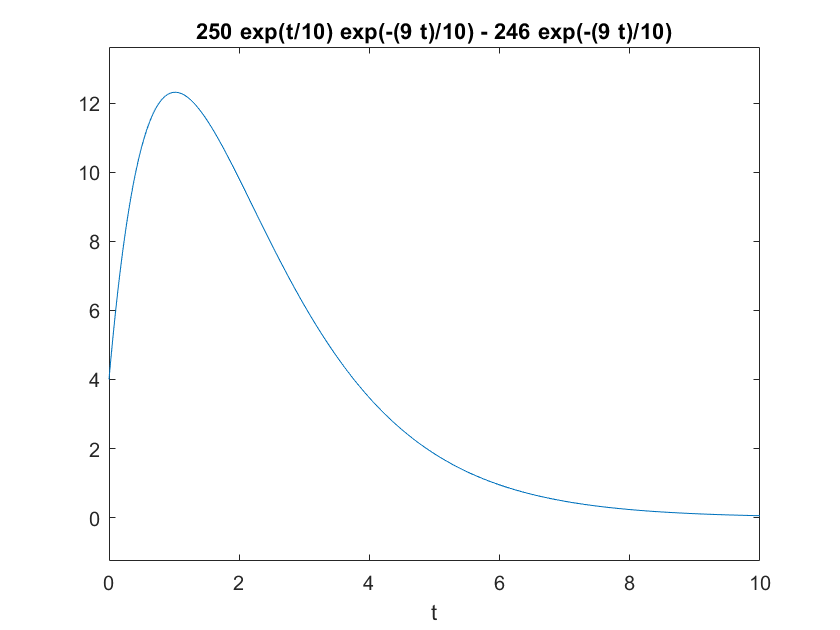

ezplot(ySol, [0,10])


t = 0.23;



% [t,y] = ode45(odefun,tspan,y0)

Simple ODEs that have a single solution component can be specified as an anonymous function in the call to the solver. The anonymous function must accept two inputs `(t,y)` even if one of the inputs is not used.

Solve the ODE

*y*′=2*t*.

Use a time interval of `[0,5]` and the initial condition `y0 = 0`.

`tspan = [0 5];`

`y0 = 0;`

`[t,y] = ode45(@(t,y) 2*t, tspan, y0);`

Plot the solution.

`plot(t,y,``'-o'``)`

The van der Pol equation is a second order ODE

where  is a scalar parameter. Rewrite this equation as a system of first-order ODEs by making the substitution . The resulting system of first-order ODEs is

The function file `vdp1.m` represents the van der Pol equation using . The variables  and  are the entries `y(1)` and `y(2)` of a two-element vector, `dydt`.

`function`` dydt = vdp1(t,y)`

`%VDP1  Evaluate the van der Pol ODEs for mu = 1`

`%`

`%   See also ODE113, ODE23, ODE45.`

`%   Jacek Kierzenka and Lawrence F. Shampine`

`%   Copyright 1984-2014 The MathWorks, Inc.`

`dydt = [y(2); (1-y(1)^2)*y(2)-y(1)];`

Solve the ODE using the `ode45` function on the time interval `[0 20]` with initial values `[2 0]`. The resulting output is a column vector of time points `t` and a solution array `y`. Each row in `y` corresponds to a time returned in the corresponding row of `t`. The first column of `y` corresponds to , and the second column to .

`[t,y] = ode45(@vdp1,[0 20],[2; 0]);`

Plot the solutions for  and  against `t`.

`plot(t,y(:,1),``'-o'``,t,y(:,2),``'-o'``)`

`title(``'Solution of van der Pol Equation (\mu = 1) with ODE45'``);`

`xlabel(``'Time t'``);`

`ylabel(``'Solution y'``);`

`legend(``'y_1'``,``'y_2'``)`